clearvars; close all
% Path to the project folder
chdir('D:\Profile\qse\files\projects\sijia_sulphurization');
% Add source file directory
addpath(genpath('scr'));

## Import

% Load directory with the raw files
LPath_ = 'data/raw/20230622_Qband/13_calib_natc60.DTA';
[x, y_, Params] = eprload(LPath_);
y = -y_{1, 1};
x = x/10 + 0.2905;

# Determine field offset

To obtain the correct field, $B_{0,\textrm{correct}} =B_{0,\textrm{raw}} +B_{\textrm{offset}}$ with $B_{\textrm{offset}} =0\ldotp 2905$mT.

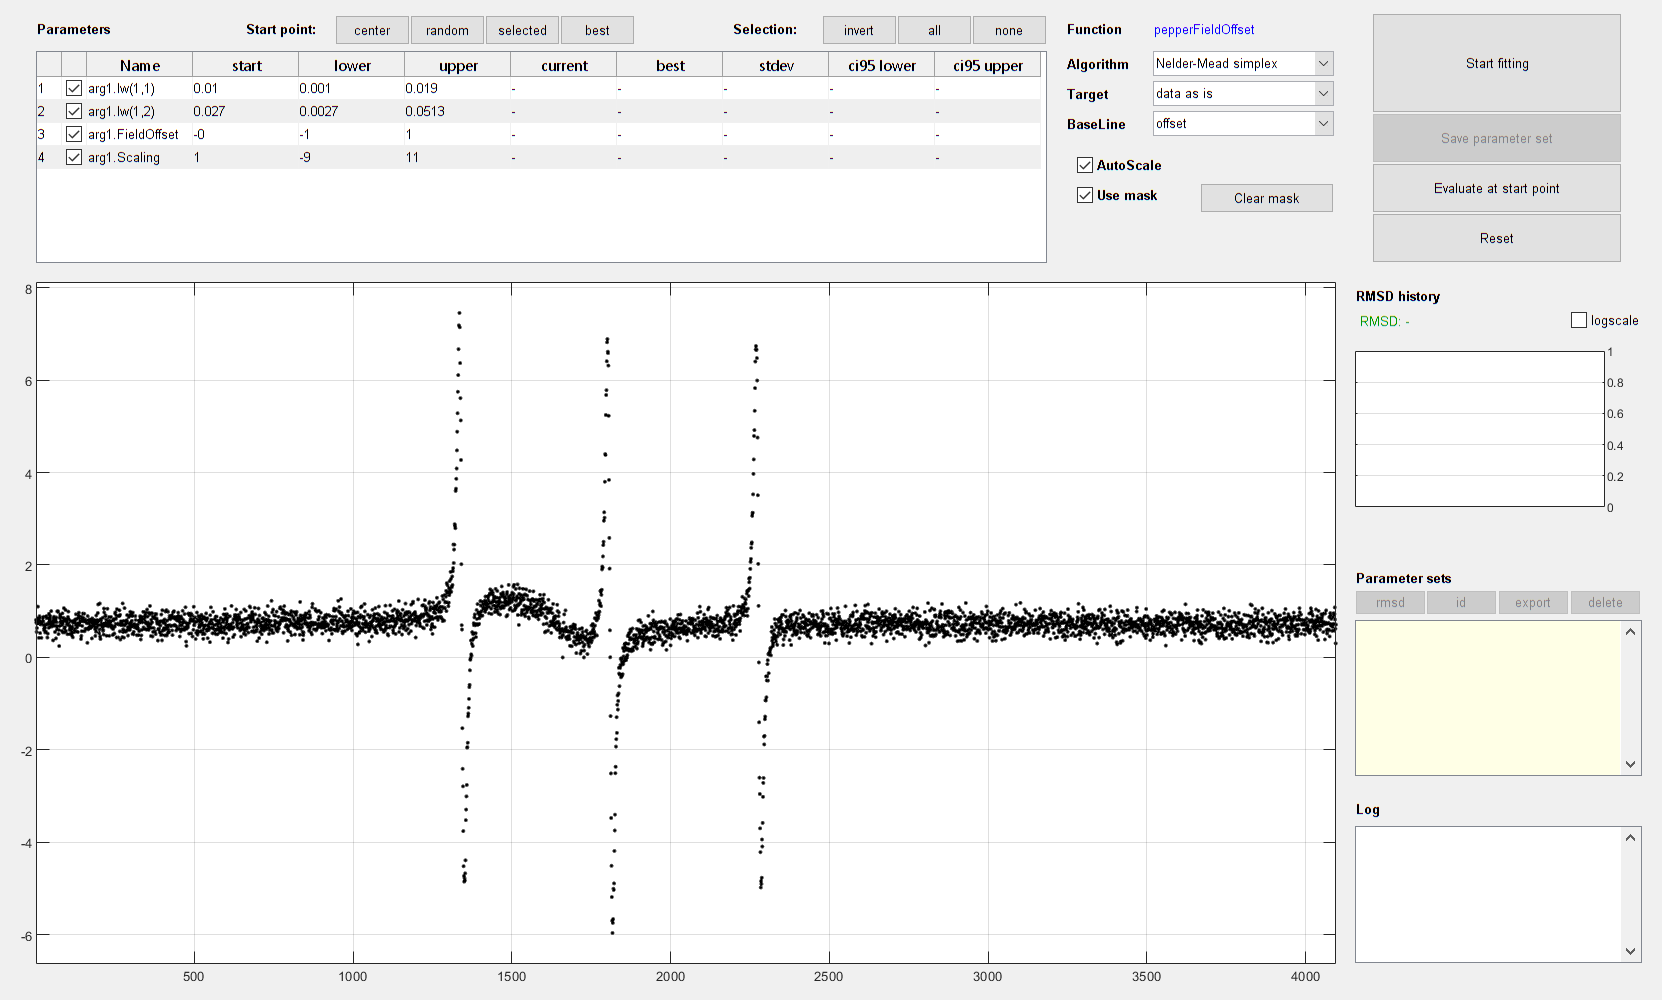

Sys.S = 3/2;
Sys.g = 2.00211; % Value from the literature
Sys.A = 15.9173; % MHz
Sys.lw = [0.01 0.027]; % mT [Gaussian Lorentzian]
Sys.Nucs = 'N';
Sys.FieldOffset = -0; % mT
Sys.Scaling = 1;

Sys2.g = 2.00211; % Value from the literature
Sys2.lw = [0.01 0.027]; % mT [Gaussian Lorentzian]
Sys2.weight = 2;

% Parameter ranges
Vary.lw = Sys.lw*9/10;
Vary.FieldOffset = 1;
Vary.Scaling = 10;

Vary2.weight = 1;

% Parameters of the experiment
Exp.mwFreq = Params.MWFQ*1e-09; % GHz
Exp.Range = [min(x) max(x)];
Exp.nPoints = numel(x);

FitOpt.BaseLine = 0;

% esfit(y, @pepperFieldOffset, {{Sys, Sys2}, Exp}, {{Vary, Vary2}}, FitOpt)
esfit(y, @pepperFieldOffset, {Sys, Exp}, {Vary}, FitOpt)

Fit.pfit

ans =     0.0134
    0.0237
   -0.2905
